# **Handwriten Digit Recognition (MNIST)**

MNIST is a handwritten digit database commonly used to test various image reconition algorithms. It contains 60,000 images for training and 10,000 images for testing.

**If you want to run this example, please download the data set from **[**Kaggle**](https://www.kaggle.com/datasets/hojjatk/mnist-dataset?resource=download)** or **[**Yann LeCun's website**](http://yann.lecun.com/exdb/mnist/)**.**

## 1. Load MNIST Data Set

The dataset has been preprocessed, so all values in the image are between 0 and 1, not $\left\lbrack 0,255\right\rbrack$.

we'll  train the neural net using `"DataTrain"`, `"LabelTrain"` and test the neural net using `"DataTest"` and `"LabelTest"`.

clear; clc; close all;
DataTrain=loadMNISTImages('train-images.idx3-ubyte');
LabelTrain=loadMNISTLabels('train-labels.idx1-ubyte');
DataTest=loadMNISTImages('t10k-images.idx3-ubyte');
LabelTest=loadMNISTLabels('t10k-labels.idx1-ubyte');
% loadMNISTImages, loadMNISTLabels function are copy from the follwing github pages:
% https://github.com/davidstutz/matlab-mnist-two-layer-perceptron/blob/master/loadMNISTImages.m

## 2. Set Up Network Structure

The images in MNIST are $28\times 28$ grayscale images reshaped into $784\times 1\;$ vectors,

so the input dimension is $784$ and the output dimension are number of class, which is $10\ldotp$

InputDimension=784; OutputDimension=10;
LayerStruct=[InputDimension,128,64,OutputDimension];
% NN.ActivationFunction='Gaussian'; % default activation.
NN.Cost='Entropy'; % For classification problems, the appropriate cost is Cross-Entropy.
NN=Initialization(LayerStruct,NN);

## 3. One Hot Encoding

First, please note that MATLAB indexing starts at one. Therefore, the class labels should be shifted by one.

LabelTest=LabelTest+1;
LabelTrain=LabelTrain+1;
LabelTrain=LabelTrain'; % Transpose the Data and Label for neural net input requirement.
LabelTest=LabelTest';

Transform original labels into one hot vector $\mathit{\mathbf{v}}\in R^{10\times 1}$ i.e.

                                                                            
$$0\to \left\lbrack \begin{array}{c}
1\\
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack ,\;\;2\to \left\lbrack \begin{array}{c}
0\\
0\\
1\\
\vdots \\
0
\end{array}\right\rbrack ,\;9\to \left\lbrack \begin{array}{c}
0\\
0\\
0\\
\vdots \\
1
\end{array}\right\rbrack$$


Perform One Hot Encoding using` NN.IndexToHot `function.

HotLabelTrain=NN.IndexToHot(LabelTrain);
HotLabelTest=NN.IndexToHot(LabelTest);

Matrix `"HotLabelTrain"` looks like :

                                                                           
$$\mathit{\mathbf{Y}}=\left\lbrack \begin{array}{cccc}
1 & 0 & \cdots  & 0\\
0 & 0 & \cdots  & 0\\
\vdots  & 1 & \cdots  & \vdots \\
\vdots  & \vdots  & \cdots  & 1\\
0 & 0 & \cdots  & 0
\end{array}\right\rbrack \in {\mathit{\mathbf{R}}}^{10\times 60000}$$


## 4. Visualize Training Set Images

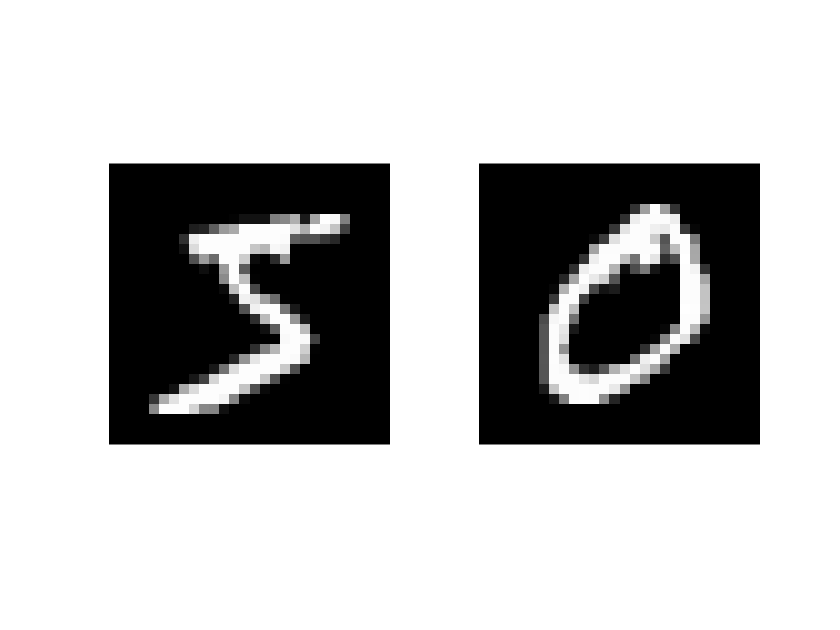

image1=DataTrain(:,1); image2=DataTrain(:,2);
image1=255*reshape(image1,28,28); image2=255*reshape(image2,28,28);
image1=uint8(image1); image2=uint8(image2);
figure;
subplot(1,2,1); imshow(image1);
subplot(1,2,2); imshow(image2);

## 5. Optimization (Training)

Solve the minimization problem posed by the classification task. i.e.

            
$${\mathit{\mathbf{W}}}^* ,{\mathit{\mathbf{b}}}^* =\textrm{argmin}\;J\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)=-\Sigma \;\log \left(\mathit{\mathbf{N}}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}},{\mathit{\mathbf{x}}}_k \right)\right){{\mathit{\mathbf{y}}}_k }_{\;}$$


where $\mathit{\mathbf{N}}\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}},\mathit{\mathbf{x}}\right)$ is output of neural net,${\mathit{\mathbf{y}}}_{k\;}$are $k$-th column vector of the one hot encoding matrix $\mathit{\mathbf{Y}}$ , and $J\left(\mathit{\mathbf{W}},\mathit{\mathbf{b}}\right)$ is the cross-entropy cost.

The state-of-the-art first order solver for neural nets training is "ADAM" (Adaptive Momentum Estimation).

option.Solver='ADAM';
option.BatchSize=512;
option.s0=8e-4;
option.MaxIteration=30;
NN=OptimizationSolver(DataTrain,HotLabelTrain,NN,option);

Iteration : 1 , Cost :       0.72152995 
Iteration : 2 , Cost :       0.33168685 
Iteration : 3 , Cost :       0.21607317 
Iteration : 4 , Cost :       0.16019820 
Iteration : 5 , Cost :       0.12495114 
Iteration : 6 , Cost :       0.10128856 
Iteration : 7 , Cost :       0.08361998 
Iteration : 8 , Cost :       0.06955158 
Iteration : 9 , Cost :       0.05894962 
Iteration : 10 , Cost :       0.05004414 
Iteration : 11 , Cost :       0.04339402 
Iteration : 12 , Cost :       0.03615505 
Iteration : 13 , Cost :       0.03068760 
Iteration : 14 , Cost :       0.02692674 
Iteration : 15 , Cost :       0.02405585 
Iteration : 16 , Cost :       0.01945985 
Iteration : 17 , Cost :       0.01656214 
Iteration : 18 , Cost :       0.01420439 
Iteration : 19 , Cost :       0.01245240 
Iteration : 20 , Cost :       0.01055248 
Iteration : 21 , Cost :       0.00932186 
Iteration : 22 , Cost :       0.00799392 
Iteration : 23 , Cost :       0.00717575 
Iteration : 24 , Cost :       0.00643291 
I

This network achieve 99.99% accuracy on training set.

## 6. Test Classification Peformance

To quickly obtain the testing set accuracy using the command `"NN.ComputeAccuracy(data,label)"`, 

please ensure that the label is in the one-hot vector form when using this command.

TestAccuracy=NN.ComputeAccuracy(DataTest,HotLabelTest)

TestAccuracy = 97.6000

## 7. Classifiy Handwriten Digits using Trained Network

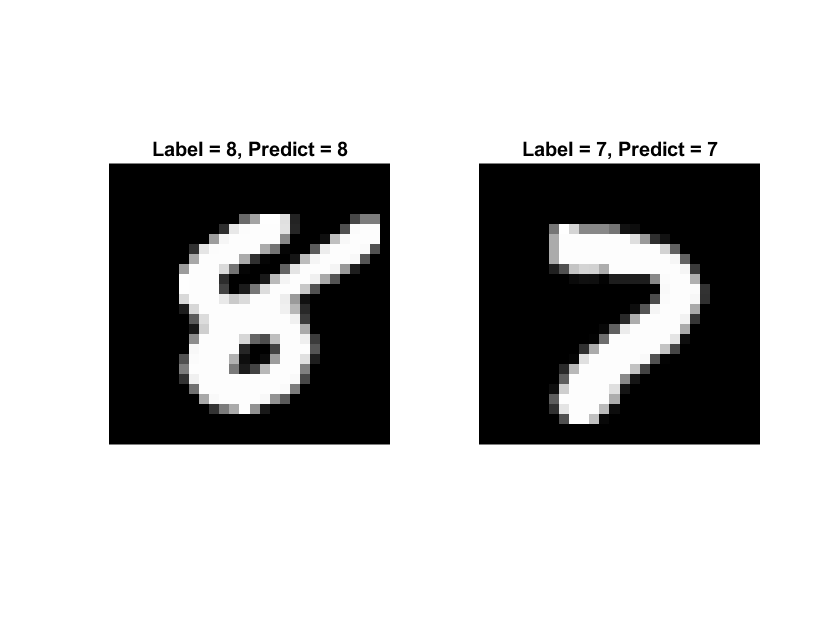

SampleIndex1=4961;   
SampleIndex2=8031;
image1=DataTest(:,SampleIndex1);
TrueLabel1=LabelTest(SampleIndex1)-1; % Shift Class Index back.
ShowImage1=255*reshape(image1,28,28); 
ShowImage1=uint8(ShowImage1);

image2=DataTest(:,SampleIndex2);
TrueLabel2=LabelTest(SampleIndex2)-1; % Shift Class Index back.
ShowImage2=255*reshape(image2,28,28);
ShowImage2=uint8(ShowImage2);

PredictedClass1=NN.Predict(image1)-1; % Shift Class Index back.
PredictedClass2=NN.Predict(image2)-1; % Shift Class Index back.
figure
subplot(1,2,1)
imshow(ShowImage1)
title(['Label = ',num2str(TrueLabel1),', Predict = ' ,num2str(PredictedClass1)'])
subplot(1,2,2)
imshow(ShowImage2)
title(['Label = ',num2str(TrueLabel2),', Predict = ' ,num2str(PredictedClass2)'])

Auxiliary functions for loading MNIST data set, the code are copy from the [GitHub page](https://github.com/davidstutz/matlab-mnist-two-layer-perceptron/blob/master/loadMNISTImages.m) : 

function images = loadMNISTImages(filename)
%loadMNISTImages returns a 28x28x[number of MNIST images] matrix containing
%the raw MNIST images

fp = fopen(filename, 'rb');
assert(fp ~= -1, ['Could not open ', filename, '']);

magic = fread(fp, 1, 'int32', 0, 'ieee-be');
assert(magic == 2051, ['Bad magic number in ', filename, '']);

numImages = fread(fp, 1, 'int32', 0, 'ieee-be');
numRows = fread(fp, 1, 'int32', 0, 'ieee-be');
numCols = fread(fp, 1, 'int32', 0, 'ieee-be');

images = fread(fp, inf, 'unsigned char');
images = reshape(images, numCols, numRows, numImages);
images = permute(images,[2 1 3]);

fclose(fp);

% Reshape to #pixels x #examples
images = reshape(images, size(images, 1) * size(images, 2), size(images, 3));
% Convert to double and rescale to [0,1]
images = double(images) / 255;

end

function labels = loadMNISTLabels(filename)
%loadMNISTLabels returns a [number of MNIST images]x1 matrix containing
%the labels for the MNIST images

fp = fopen(filename, 'rb');
assert(fp ~= -1, ['Could not open ', filename, '']);

magic = fread(fp, 1, 'int32', 0, 'ieee-be');
assert(magic == 2049, ['Bad magic number in ', filename, '']);

numLabels = fread(fp, 1, 'int32', 0, 'ieee-be');

labels = fread(fp, inf, 'unsigned char');

assert(size(labels,1) == numLabels, 'Mismatch in label count');

fclose(fp);

end